# Doing Differential Equations with MatLab

clear, clc, close

tstart = 0;
tend = 30.0;

A0 = 20; % the initial value of A at time=0
B0 = 0;
c = 0.5

c = 0.5000

d = 0.75;
e = 0.25;

pracfun = @(t, x) [
    c*x(1) - d*x(1);
    d*x(1) - e*x(2);
]; 
[t, pracfunOUT] = ode45(pracfun, [tstart, tend], [A0 B0])

t =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0002


pracfunOUT =    20.0000         0
   20.0000    0.0001
   20.0000    0.0001
   19.9999    0.0002
   19.9999    0.0002
   19.9998    0.0005
   19.9998    0.0007
   19.9997    0.0010
   19.9996    0.0012
   19.9992    0.0025


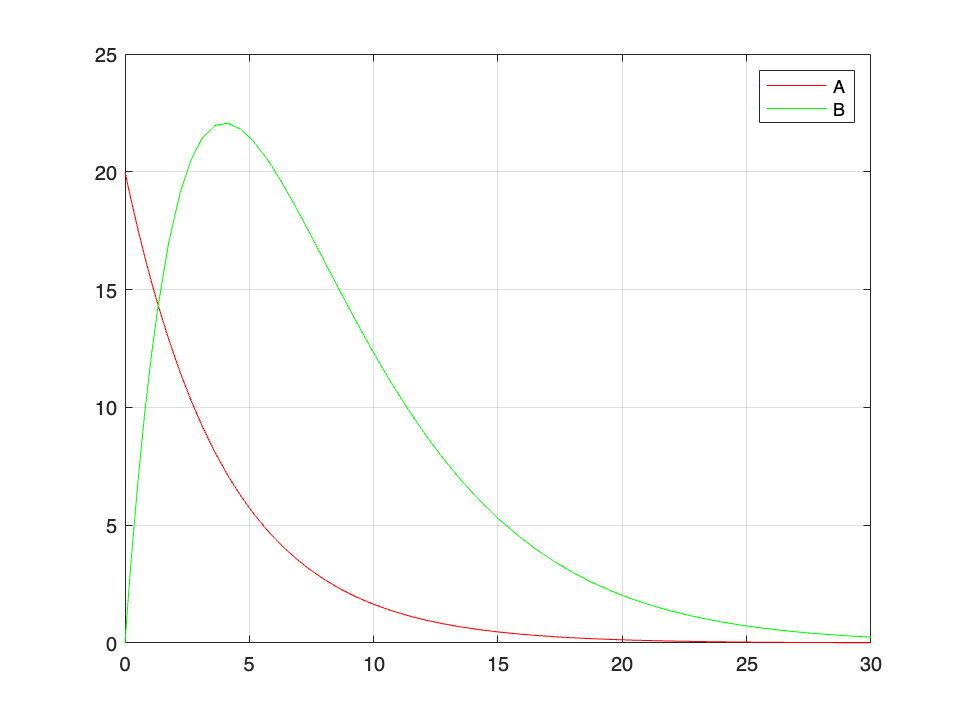

figure("Name", "ODE Plot")
plot(t, pracfunOUT(:,1), 'color', 'r');
hold on;
plot(t, pracfunOUT(:,2), 'color', 'g')
grid on
legend("A", "B")
hold off